## **CYKLY SPALOVACÍCH TURBÍN - BRAYTONŮV CYKLUS**

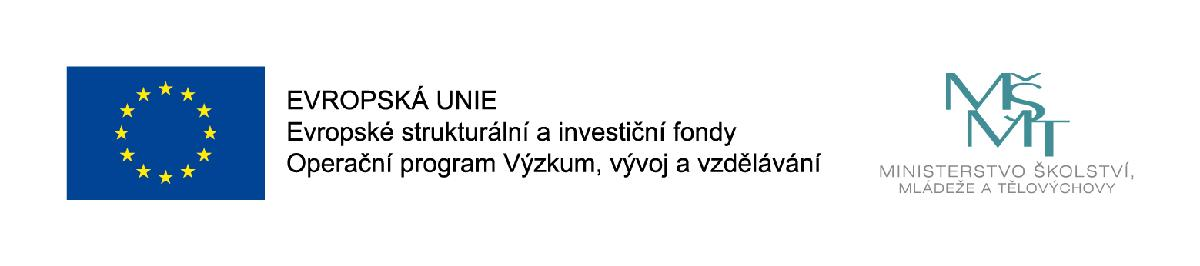

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

## **SIEMENS SGT5-8000H**

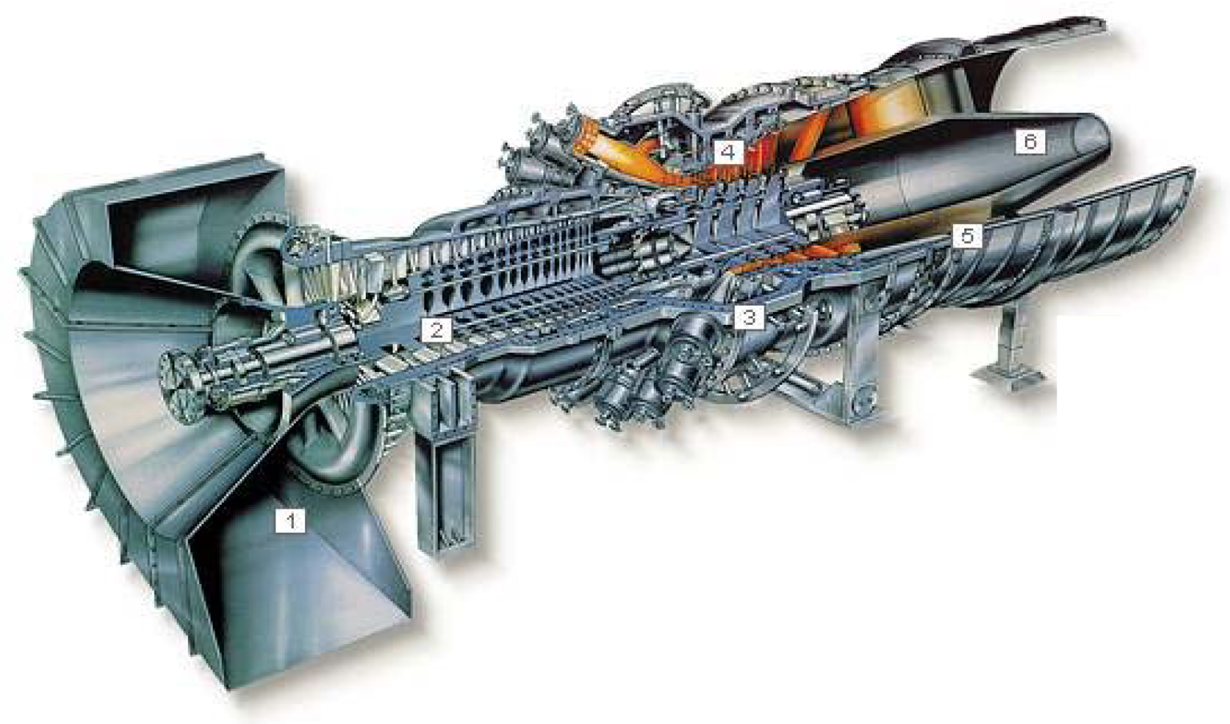

**Maximální teplota spalin:** 1190 °C

**Teplota výstupních spalin:** 565 °C

**Průtok:** 640 kg.s-1 

**NOx****:** 25 ppm

**Výkon: **340 MW  **účinnost **40 %

**V paroplynovém cyklu účinnost:** 60 %

## **BRAYTONŮVCYKLUS**

*Cyklus **Braytonův* se skládá ze dvou izobar a ze dvou adiabat. Tento cyklus nejdříve použil v rovnotlakém spalovacím motoru na svíti­plyn *Ericsson *(1833) a *Brayton* (1873). Podle téhož cyklu pracovaly teplovzdušné stroje. V novější době se tohoto cyklu užívá u rovnotlakých plynových turbín a u leteckých proudových motorů s kontinuálním spalováním. Termickou účinnost stanovíme z přivedeného a odvedeného tepla.

Zařízení je uspořádáno tak, že plynová turbína, kompresor, popřípadě čerpadlo, jsou na společné hřídeli.

Cyklus je otevřený. Kompresor nasává stále čerstvý vzduch z atmosféry a rovněž plyny prošlé ohřívákem proudí do atmosféry. 

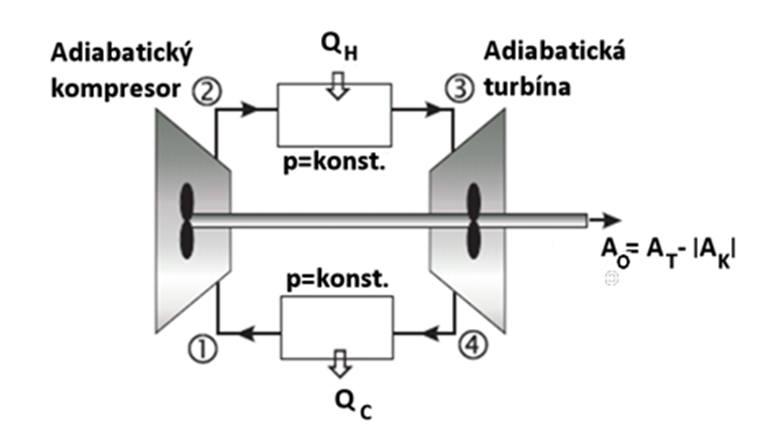

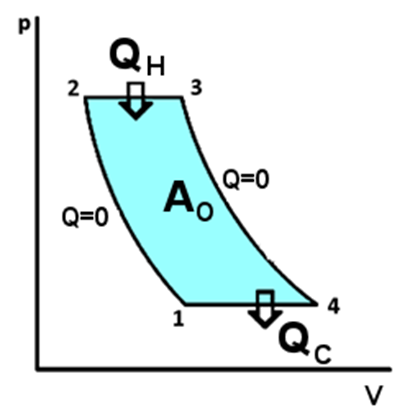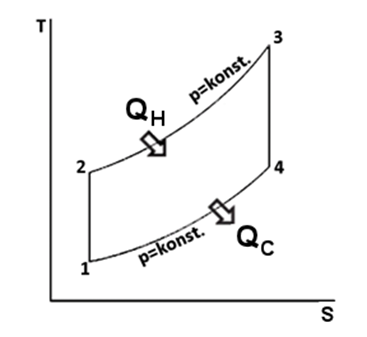

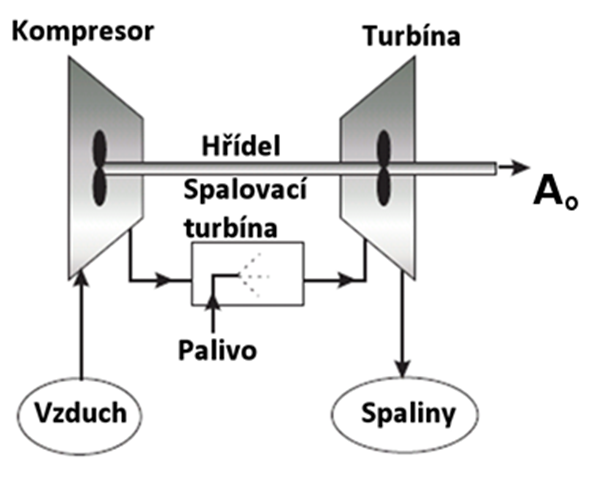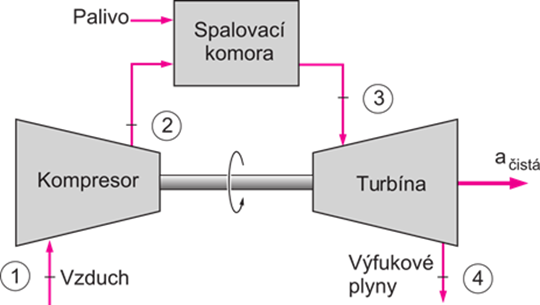

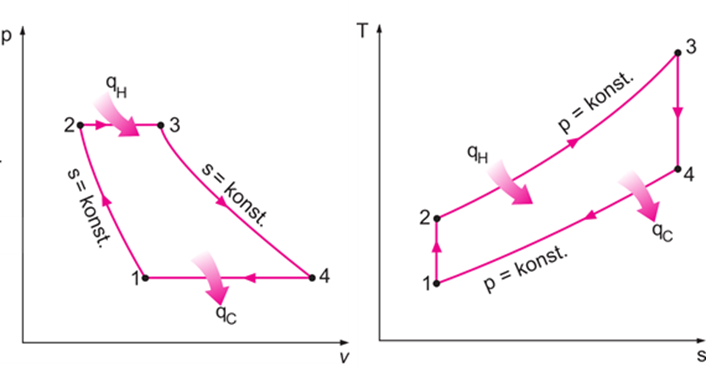

Přívedené a odvedené teplo:


$$${Q_H} = m{c_p}({T_3} - {T_2})$$$
                            
$$${Q_C} = m{c_p}({T_1} - {T_4})$$$


Kompresní poměr  $${\epsilon} = \frac{V_1}{V_2}$$

**Tlakový poměr**  $${\epsilon_p}  = {\Pi} = \frac{p_2}{p_1}$$

Stupeň plnění  $${\phi} = \frac{V_3}{V_2}$$

**Výpočet termické účinnosti:**


$$\[{\eta _t}{\kern 1pt}  = 1{\kern 1pt}  - \frac{{\left| {{Q_C}} \right|}}{{{Q_H}}} = 1{\kern 1pt}  - \frac{{m{c_p}({T_4} - {T_1})}}{{m{c_P}({T_3} - {T_2})}} = 1 - \frac{{{T_1}}}{{{T_2}}}\left( {\frac{{\frac{{{T_4}}}{{{T_1}}} - 1}}{{\frac{{{T_3}}}{{{T_2}}} - 1}}} \right)\]$$



$$\[{\eta _t} = 1 - \frac{{{T_1}}}{{{T_2}}} = 1 - {\left( {\frac{{{p_1}}}{{{p_2}}}} \right)^{\frac{{\kappa  - 1}}{\kappa }}} = 1 - {\left( {{\varepsilon _p}} \right)^{\frac{{1 - \kappa }}{\kappa }}} = 1 - {\left( {\frac{1}{\varepsilon }} \right)^{\kappa  - 1}}\]$$


**Konečný vytah pro termickou účinnot:**

# 
$$\[{\eta _t} = 1 - {\left( {{\varepsilon _p}} \right)^{\frac{{1 - \kappa }}{\kappa }}}\]$$


# 
$$\[{\eta _t} = f\left( {\kappa ,{\varepsilon _P}} \right)\]$$


Termická účinnost *Braytonova**cyklu* závisí stejně jako u zážehového cyklu pouze na tlakovém poměru.

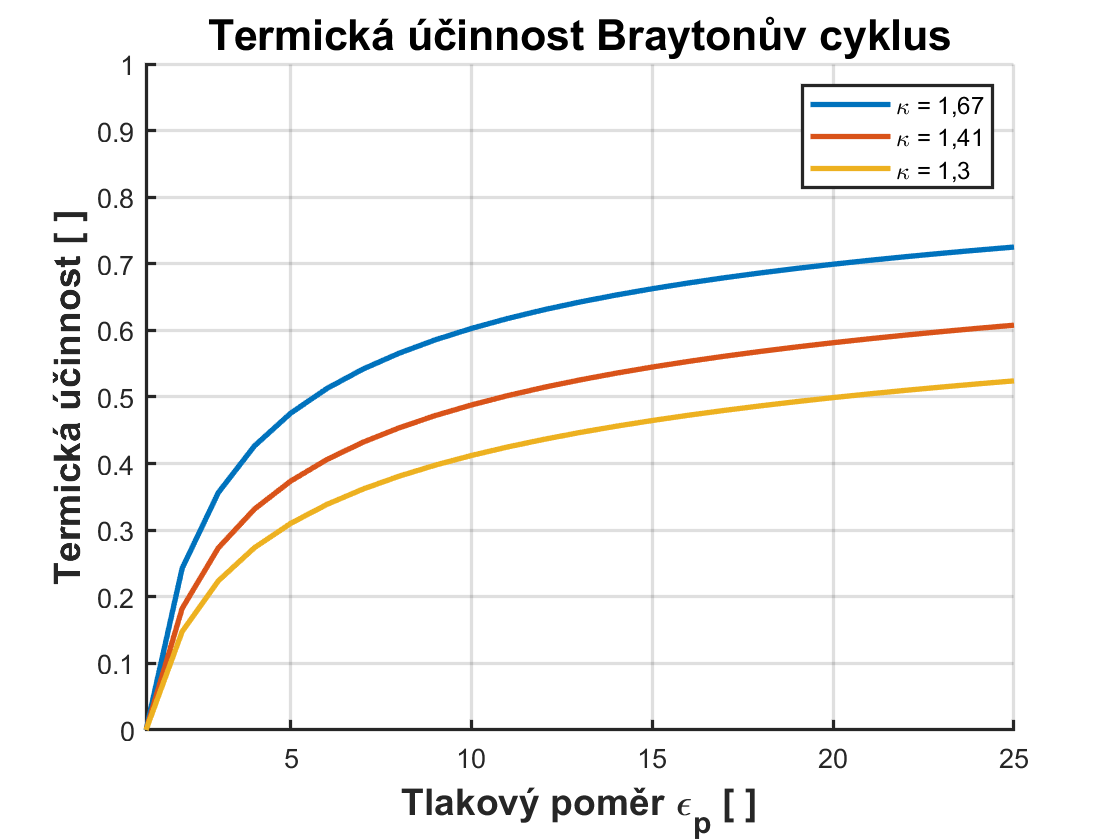

clear;
clc;
figure;
i = 1;
eps_p = zeros(1, 25);
eta_t_1 = zeros(1, 25);
eta_t_2 = zeros(1, 25);
eta_t_3 = zeros(1, 25);
for eps=1:1.0:25
    eps_p(i) = eps;
    eta_t_1(i) = 1-(eps)^((1-kappaB(1))/kappaB(1));
    eta_t_2(i) = 1-(eps)^((1-kappaB(2))/kappaB(2));
    eta_t_3(i) = 1-(eps)^((1-kappaB(3))/kappaB(3));
    i = i + 1;
end
title('Termická účinnost Braytonův cyklus','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Tlakový poměr \epsilon_p [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Termická účinnost [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([1 25]);
ylim([0 1]);
set(gca, 'linewidth',1.2);
hold on;
plot(eps_p,eta_t_1,'-','linewidth',2);
plot(eps_p,eta_t_2,'-','linewidth',2);
plot(eps_p,eta_t_3,'-','linewidth',2);
grid on;
legend('\kappa = 1,67','\kappa = 1,41','\kappa = 1,3')
hold off;

# $${\eta _t}$$lze zvyšovat tlakovým poměrem

# Problém zvyšování účinnosti je, že s rostoucím tlakovým poměrem roste teplota na lopatkách turbíny.

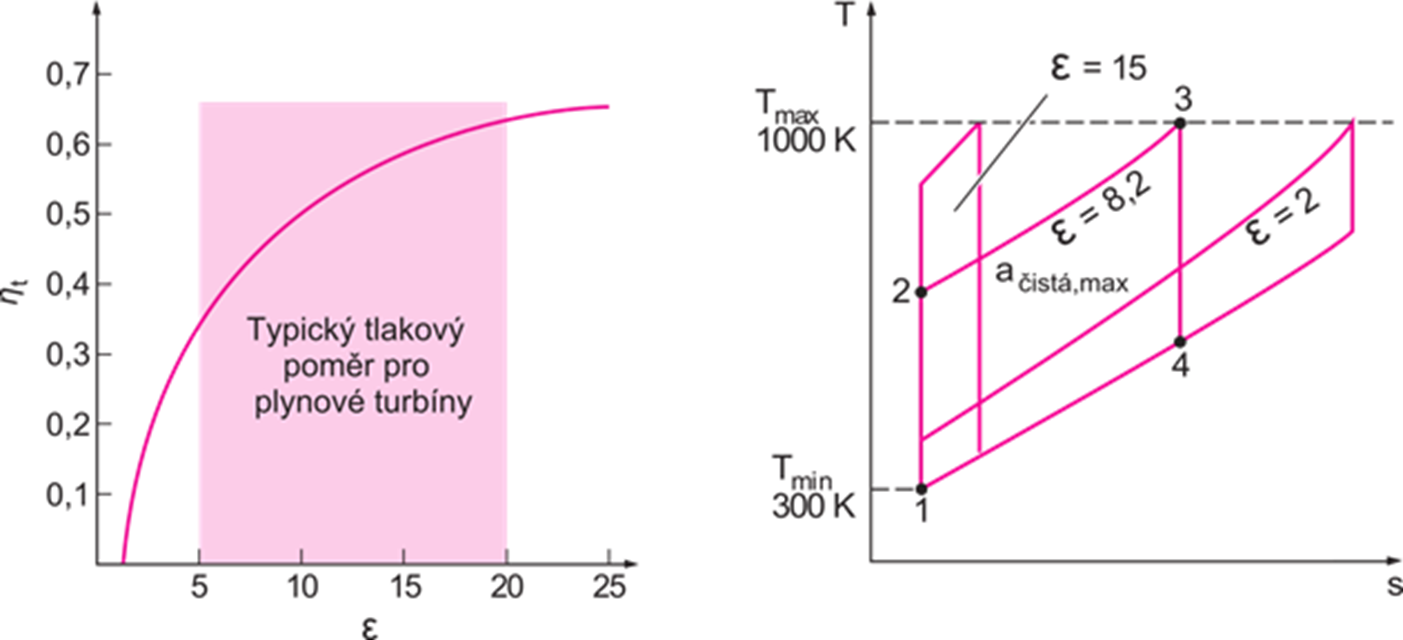

Tlakový poměr v praxi mezi 5 až 20, jsme omezeni maximální teplotou cca Tmax=1600 K

Vztah pro výpočet optimálního tlakového poměru, při kterém bude turbína dosahovat nejvyšší výkon a nepřekročí maximální dovolenou teplotu.


$$\[pro\;\max \;{A_o}\;\;\;\;{\varepsilon _P} = {\left( {\frac{{{T_{\max }}}}{{{T_{\min }}}}} \right)^{\frac{\kappa }{{2\kappa  - 2}}}}\]$$


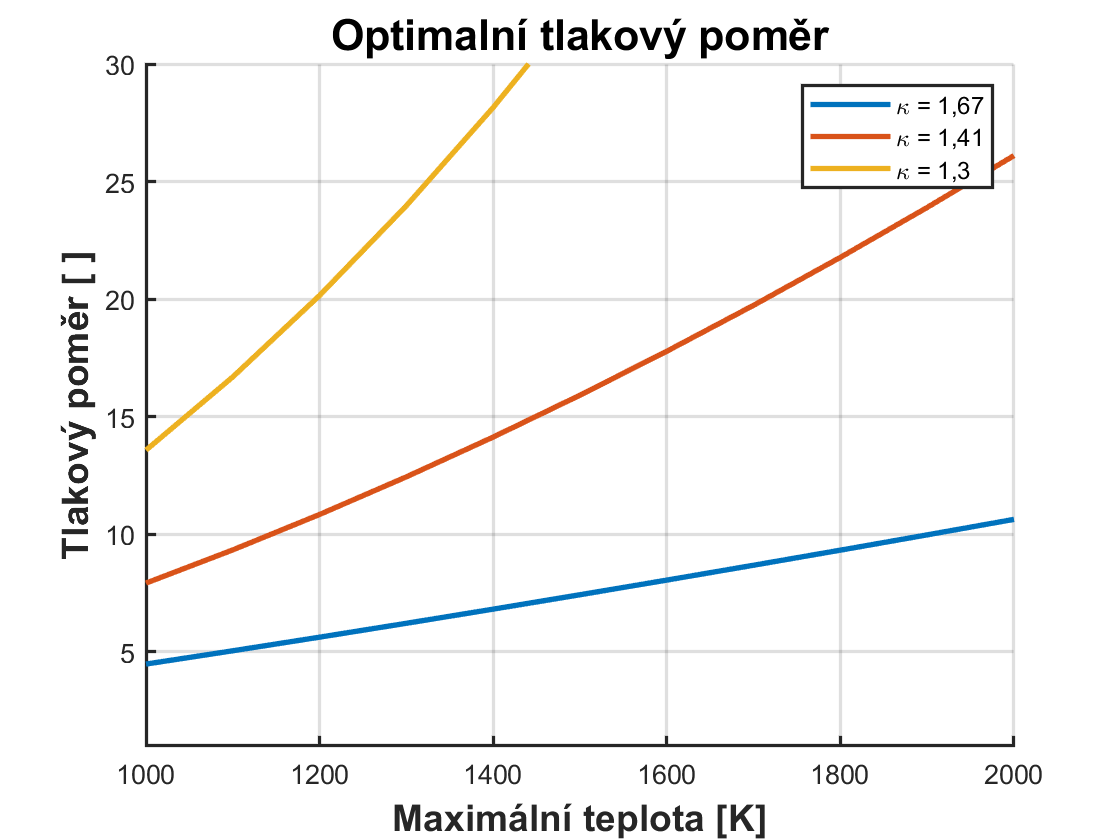

figure;
i = 1;
Tmin = 300;
T_max = zeros(1,11);
eta_p_1 = zeros(1, 11);
eta_p_2 = zeros(1, 11);
eta_p_3 = zeros(1, 11);
for Tm=1000:100.0:2000
    T_max(i) = Tm;
    eta_p_1(i) = (T_max(i)/Tmin)^(kappaB(1)/(2*kappaB(1)-2));
    eta_p_2(i) = (T_max(i)/Tmin)^(kappaB(2)/(2*kappaB(2)-2));
    eta_p_3(i) = (T_max(i)/Tmin)^(kappaB(3)/(2*kappaB(3)-2));
    i = i + 1;
end
title('Optimalní tlakový poměr','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Maximální teplota [K]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Tlakový poměr [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([1000 2000]);
ylim([1 30]);
set(gca, 'linewidth',1.2);
hold on;
plot(T_max,eta_p_1,'-','linewidth',2);
plot(T_max,eta_p_2,'-','linewidth',2);
plot(T_max,eta_p_3,'-','linewidth',2);
grid on;
legend('\kappa = 1,67','\kappa = 1,41','\kappa = 1,3')
hold off;

### Příklad

Ideální cyklus plynové turbíny pracuje s přívodem tepla při konstantním tlaku (Braytonův cyklus). Maximální teplota před turbínou je 900 °C a teplota nasávaného vzduchu je 20 °C a tlak 980 hPa. Tlakový poměr kompresoru je 8. Vypočítejte měrnou práci cyklu a měrné přivedené a odvedené teplo, dále termickou účinnost a výkon turbíny pokud je množství nasávaného vzduchu 5 kg/s.  Pracovní látka má vlastnosti vzduchu (r = 287 J/kgK, kappa = 1,40). Nakreslete p-v a T-s diagram.

clear all;
p1hPa  = 980.0; % [hPa] tlak nasávaného vzduchu
mdot   = 5.0;   % [kg/s] hmotnostní tok vzduchu turbínou
t1C   = 20;     % [C]  teplota nasávaného vzduchu
epsp  = 8;      % [-]  tlakový poměr
t3C   = 900.0;  % [C]  maximální teplota
r = 287.0;      % [J/kgK] plynová konstanta
kappa = 1.40;   %
%% 
cv = 1/(kappa-1) * r;
cp = cv * kappa;
%% Bod 1
T1 = C2K(t1C);
p1 = hPa2Pa(p1hPa);
%% Bod 2
p2 = p1 * epsp;
T2 = T1*(epsp)^((kappa-1)/kappa);
%% Bod 3
T3 = C2K(t3C);
p3 = p2;
%% Bod 4
p4 = p1;
T4 = T3*(p4/p3)^((kappa-1)/kappa);
%% Měrná práce a tepla
qh = cp * (T3-T2);
qc = cp * (T1-T4);
ao =  qh - abs(qc);
Pt = mdot * ao;
etat = ao / qh;

%% výstupní data
fprintf('p1 : %.1f kPa T1 :  %.1f K \n',Pa2kPa(p1),  T1);

p1 : 98.0 kPa T1 :  293.1 K 


fprintf('p2 : %.1f kPa T2 :  %.1f K \n',Pa2kPa(p2),  T2);

p2 : 784.0 kPa T2 :  531.0 K 


fprintf('p3 : %.1f kPa T3 :  %.1f K \n',Pa2kPa(p3),  T3);

p3 : 784.0 kPa T3 :  1173.2 K 


fprintf('p4 : %.1f kPa T4 :  %.1f K \n',Pa2kPa(p4),  T4);

p4 : 98.0 kPa T4 :  647.6 K 


fprintf('Přivedené měrné teplo : %.1f [kJ/kg]\n',J2kJ(qh));

Přivedené měrné teplo : 645.0 [kJ/kg]


fprintf('Odvedené měrné teplo  : %.1f [kJ/kg]\n',J2kJ(qc));

Odvedené měrné teplo  : -356.1 [kJ/kg]


fprintf('Měrní práce cyklu     : %.1f [kJ/kg]\n',J2kJ(ao));

Měrní práce cyklu     : 288.9 [kJ/kg]


fprintf('Výkon turbíny         : %.1f [kW]\n',W2kW(Pt));

Výkon turbíny         : 1444.7 [kW]


fprintf('Termická účinnost     : %.3f\n',etat);

Termická účinnost     : 0.448


### Grafy

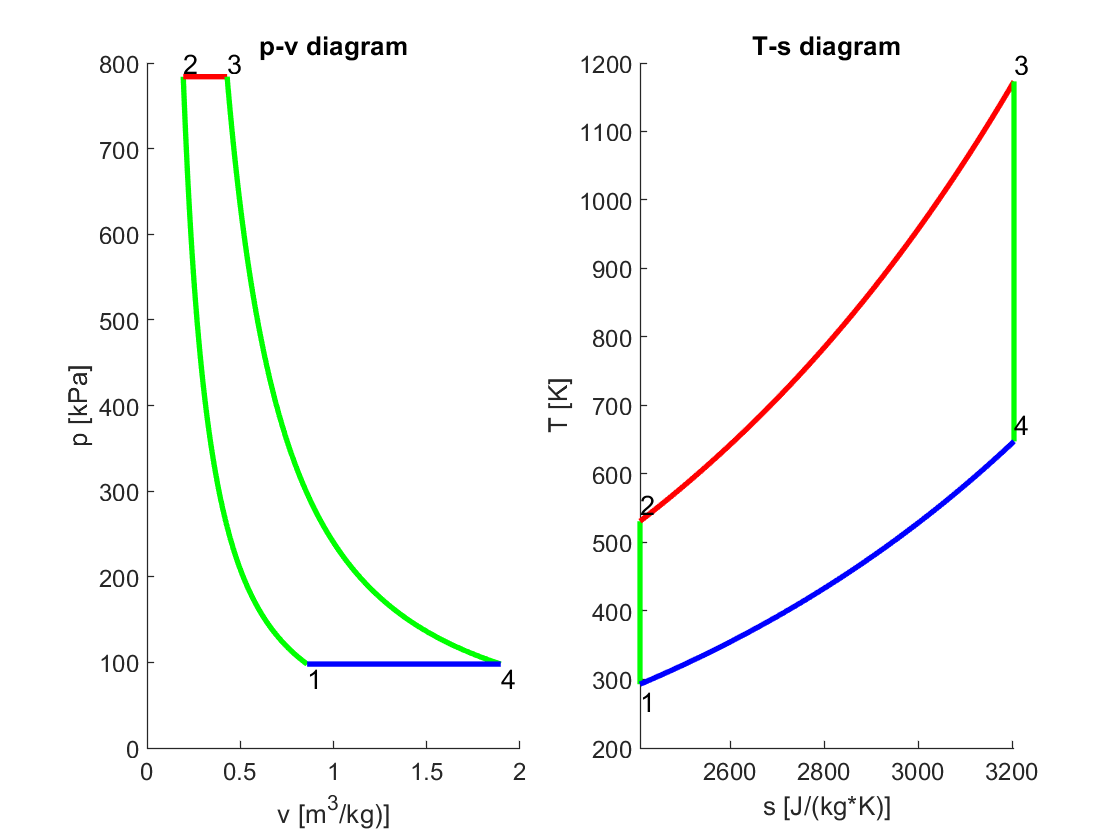

figure;
v1 = r * T1/ p1;
v2 = r * T2/ p2;
v3 = r * T3/ p3;
v4 = r * T4/ p4;

pv1 = linspace(p1,p2,180);
Vv1 = zeros([1,180]);
Tv1 = zeros([1,180]);
Sv1 = zeros([1,180]);

for i=2:180
  Tv1(i) = T1*(pv1(i)/p1)^((kappa-1)/kappa);
  Vv1(i) = r * Tv1(i)/ pv1(i);
  Sv1(i)=cp*log(Tv1(i))-r*log(pv1(i));
end
pv1(1) = p1;
pv1(180) = p2;
Vv1(1) = v1;
Vv1(180) = v2;
Tv1(1) = pv1(1) * Vv1(1) / r;
Sv1(1)= cp*log(Tv1(1))- r*log(pv1(1));

Vv2 = linspace(v2,v3,180);
pv2 = zeros([1,180]);
Tv2 = zeros([1,180]);
Sv2 = zeros([1,180]);
for i=2:180
  pv2(i)= p2;
  Tv2(i) = pv2(i) * Vv2(i) / r;
  Sv2(i)= cp*log(Tv2(i))- r*log(pv2(i));
end
pv2(1) = p2;
pv2(180) = p3;
Vv2(1) = v2;
Vv2(180) = v3;
Tv2(1) = pv2(1) * Vv2(1) / r;
Sv2(1)= cp*log(Tv2(1))- r*log(pv2(1));

Vv3 = linspace(v3,v4,180);
pv3 = zeros([1,180]);
Tv3 = zeros([1,180]);
for i=2:180
  pv3(i)=p3*v3^kappa/Vv3(i)^kappa;
  Tv3(i) = pv3(i) * Vv3(i) / r;
  Sv3(i)= cp*log(Tv3(i))- r*log(pv3(i));    
end
pv3(1) = p3;
pv3(180) = p4;
Vv3(1) = v3;
Vv3(180) = v4;
Tv3(1) = pv3(1) * Vv3(1) / r;
Sv3(1)= cp*log(Tv3(1))- r*log(pv3(1));    

Vv4 = linspace(v4,v1,180);
pv4 = zeros([1,180]);
Tv4 = zeros([1,180]);
Sv4 = zeros([1,180]);
for i=2:180
  pv4(i)= p1;
  Tv4(i) = pv4(i) * Vv4(i) / r;
  Sv4(i)= cp*log(Tv4(i))- r*log(pv4(i));
end
pv4(1) = p4;
pv4(180) = p1;
Vv4(1) = v4;
Vv4(180) = v1;
Tv4(1) = pv4(1) * Vv4(1) / r;
Sv4(1)= cp*log(Tv4(1))-r*log(pv4(1));

% Vykreslení diagramu
figure;
subplot(1,2,1);
hold on;
plot(Vv1,pv1/1000.0,'g-','linewidth',2);
plot(Vv2,pv2/1000.0,'r-','linewidth',2);
plot(Vv3,pv3/1000.0,'g-','linewidth',2);
plot(Vv4,pv4/1000.0,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Vv1(1),pv1(1)/1000.0-16,'1');
text(Vv2(1),pv2(1)/1000.0+16,'2');
text(Vv3(1),pv3(1)/1000.0+16,'3');
text(Vv4(1),pv4(1)/1000.0-16,'4');
% název grafu a popisy os
title('p-v diagram')
xlabel('v [m^3/kg)]')
ylabel('p [kPa]')                     
subplot(1,2,2);
hold on;
plot(Sv1,Tv1,'g-','linewidth',2);
plot(Sv2,Tv2,'r-','linewidth',2);
plot(Sv3,Tv3,'g-','linewidth',2);
plot(Sv4,Tv4,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Sv1(1),Tv1(1)-25,'1');
text(Sv2(1),Tv2(1)+25,'2');
text(Sv3(1),Tv3(1)+25,'3');
text(Sv4(1),Tv4(1)+25,'4');
% název grafu a popisy os
title('T-s diagram');
xlabel('s [J/(kg*K)]');
ylabel('T [K]');

### Lokální funkce 

Poissonova konstanta

function [result] = kappaB(atom)
              switch atom
                  case 1  
                    result = 1.67;
                  case 2
                    result = 1.41;
                  case 3  
                    result = 1.3;  
                  otherwise
                    result = 1.3;  
              end     
end

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end

function [kJ] = J2kJ(J)
kJ = J/1000;
end